downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'_ff', 'Intracellular', 'Excitation'};
mustHave_2b = {'_ff', 'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

coordinates = zeros(0, 2);
directions = [0:45:315];
responsesByDirection_exc = zeros(0, numel(directions));
tcAreas_exc = zeros(0, 1);
DSIs_exc = [];
responsesByDirection_inh = zeros(0, numel(directions));
tcAreas_inh = zeros(0, 1);
DSIs_inh = [];
firstDownIndex_exc = 0;
firstDownIndex_inh = 0;
inhibitionIndices = [];
excitationIndices = [];
for i = 1:size(ups, 1)+size(downs, 1)
    if i <= size(ups, 1)
        struct_i = ups{i, 2};
    else
        struct_i = downs{i-size(ups, 1), 2};
    end
    [loc_exc, pass_exc] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inh, pass_inh] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    if pass_exc && pass_inh
        continue
    end
    
    try
        [coordinates_x, coordinates_y] = pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        coordinates = [coordinates; -coordinates_x, coordinates_y];
    catch
        continue
    end
    
    
    if ~pass_exc
        if i>size(ups, 1) && firstDownIndex_exc==0 %mark the index that separates up and down cells just in case you want to split the data in this way at some point
            firstDownIndex_exc = size(responsesByDirection_exc, 1) + 1;
        end
        excitationIndices(end + 1) = 1;
        
        [~, leaf] = sort(loc_exc.Analysis_Results.Orientation);
        responses = loc_exc.Analysis_Results.maxNegativePeakByEpoch;
        dirs = loc_exc.Analysis_Results.orientationByEpoch;
        tc = zeros(1, numel(directions));
        for j = 1:numel(directions)
            tc(j) = mean(responses(dirs == directions(j)));
        end
        responsesByDirection_exc(end+1, :) = tc;
        tcAreas_exc(end + 1) = trapz([directions, 360], -[tc, tc(1)])/360;
        DSIs_exc(end + 1) = calculateDSI(directions, -tc);
    else
        excitationIndices(end + 1) = 0;
    end
    
    if ~pass_inh
        if i>size(ups, 1) && firstDownIndex_inh==0 %mark the index that separates up and down cells just in case you want to split the data in this way at some point
            firstDownIndex_inh = size(responsesByDirection_inh, 1) + 1;
        end
        inhibitionIndices(end + 1) = 1;
        
        [~, leaf] = sort(loc_inh.Analysis_Results.Orientation);
        responses = loc_inh.Analysis_Results.maxPositivePeakByEpoch;
        dirs = loc_inh.Analysis_Results.orientationByEpoch;
        tc = zeros(1, numel(directions));
        for j = 1:numel(directions)
            tc(j) = mean(responses(dirs == directions(j)));
        end
        responsesByDirection_inh(end+1, :) = tc;
        tcAreas_inh(end + 1) = trapz([directions, 360], [tc, tc(1)])/360;
        DSIs_inh(end + 1) = calculateDSI(directions, tc);
    else
        inhibitionIndices(end + 1) = 0;
    end
    
end


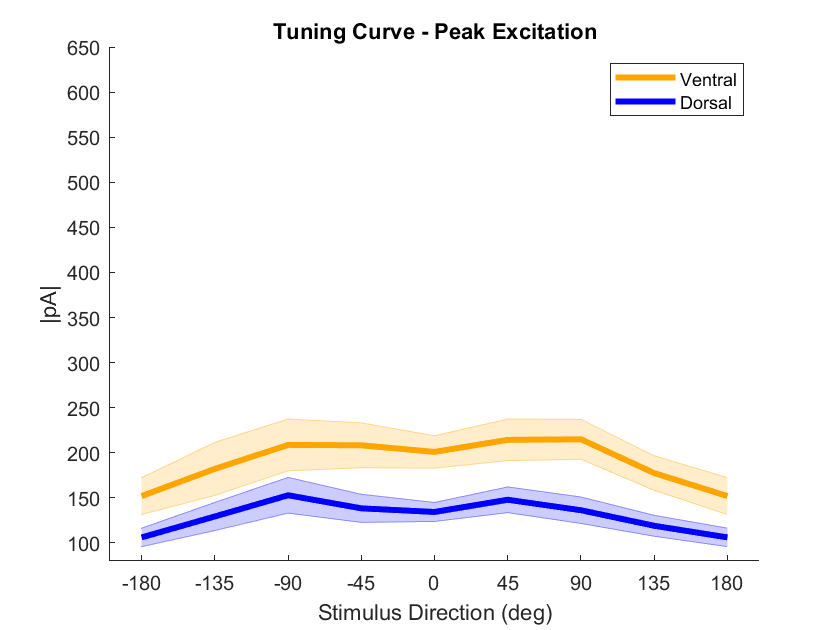

%Coordinates
dorsalIndices = coordinates(:, 2) > 0;
ventralIndices = coordinates(:, 2) < 0;

%align and rotate the tuning curves of up and down cells
downTCs_exc = responsesByDirection_exc(firstDownIndex_exc:end, :);
downTCsRotated_exc = downTCs_exc(:, [5:8, 1:4]);
responsesByDirection_aligned_exc = [responsesByDirection_exc(1:firstDownIndex_exc - 1, :); downTCsRotated_exc];
responsesByDirection_aligned_rotated_exc = responsesByDirection_aligned_exc(:, [7, 8, 1:6]);

%align and rotate the tuning curves of up and down cells
downTCs_inh = responsesByDirection_inh(firstDownIndex_inh:end, :);
downTCsRotated_inh = downTCs_inh(:, [5:8, 1:4]);
responsesByDirection_aligned_inh = [responsesByDirection_inh(1:firstDownIndex_inh - 1, :); downTCsRotated_inh];
responsesByDirection_aligned_rotated_inh = responsesByDirection_aligned_inh(:, [7, 8, 1:6]);

SE_F = @(m) std(m)/sqrt(size(m, 1));

exc_dorsal_indices = logical([]);
for i = 1:numel(excitationIndices)
    if excitationIndices(i)
        if dorsalIndices(i)
            exc_dorsal_indices(end + 1) = 1;
        else
            exc_dorsal_indices(end + 1) = 0;
        end
    end
end
exc_ventral_indices = ~exc_dorsal_indices;

inh_dorsal_indices = logical([]);
for i = 1:numel(inhibitionIndices)
    if inhibitionIndices(i)
        if dorsalIndices(i)
            inh_dorsal_indices(end + 1) = 1;
        else
            inh_dorsal_indices(end + 1) = 0;
        end
    end
end
inh_ventral_indices = ~inh_dorsal_indices;

meanDorsal_exc = mean(responsesByDirection_aligned_rotated_exc(exc_dorsal_indices, :));
SEM_dorsal_exc = SE_F(responsesByDirection_aligned_rotated_exc(exc_dorsal_indices, :));
meanVentral_exc = mean(responsesByDirection_aligned_rotated_exc(exc_ventral_indices, :));
SEM_ventral_exc = SE_F(responsesByDirection_aligned_rotated_exc(exc_ventral_indices, :));

figure
title('Tuning Curve - Peak Excitation')
hold on
shadedErrorBar([-180:45:180], -meanVentral_exc([1:8, 1]), SEM_ventral_exc([1:8, 1]),  'lineprops', {'Color', [255, 165, 0]./255, 'LineWidth', 3})
shadedErrorBar([-180:45:180], -meanDorsal_exc([1:8, 1]), SEM_dorsal_exc([1:8, 1]),  'lineprops', {'Color', [0, 0, 255]./255, 'LineWidth', 3})
xticks([-180:45:180])
xlabel('Stimulus Direction (deg)')
ylabel('|pA|')
legend('Ventral', 'Dorsal')
ylim([80 650])

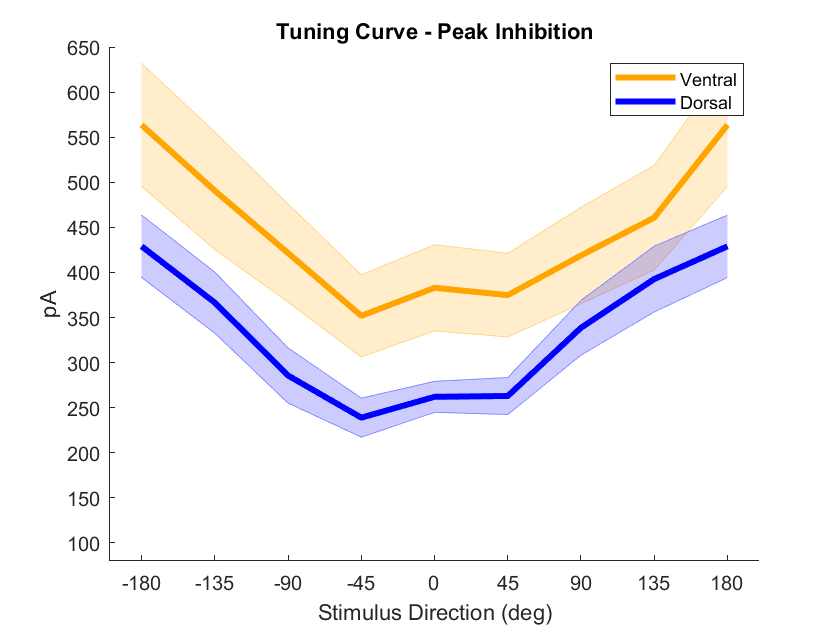


meanDorsal_inh = mean(responsesByDirection_aligned_rotated_inh(inh_dorsal_indices, :));
SEM_dorsal_inh = SE_F(responsesByDirection_aligned_rotated_inh(inh_dorsal_indices, :));
meanVentral_inh = mean(responsesByDirection_aligned_rotated_inh(inh_ventral_indices, :));
SEM_ventral_inh = SE_F(responsesByDirection_aligned_rotated_inh(inh_ventral_indices, :));

figure
title('Tuning Curve - Peak Inhibition')
hold on
shadedErrorBar([-180:45:180], meanVentral_inh([1:8, 1]), SEM_ventral_inh([1:8, 1]),  'lineprops', {'Color', [255, 165, 0]./255, 'LineWidth', 3})
shadedErrorBar([-180:45:180], meanDorsal_inh([1:8, 1]), SEM_dorsal_inh([1:8, 1]),  'lineprops', {'Color', [0, 0, 255]./255, 'LineWidth', 3})
xticks([-180:45:180])
xlabel('Stimulus Direction (deg)')
ylabel('pA')
legend('Ventral', 'Dorsal')
ylim([80 650])

## Tuning curve areas

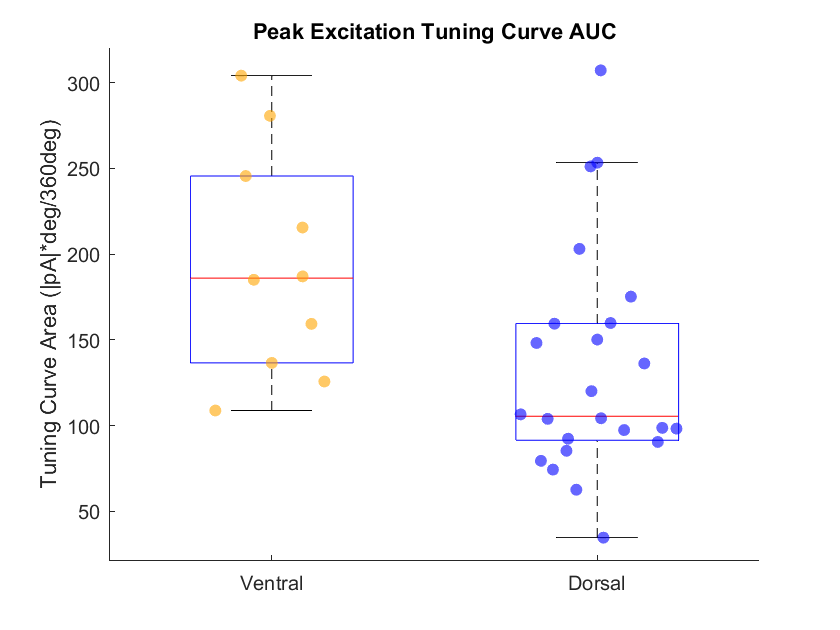

ventralTCAreas_exc = tcAreas_exc(exc_ventral_indices);
dorsalTCAreas_exc = tcAreas_exc(exc_dorsal_indices);
allPoints = [ventralTCAreas_exc'; dorsalTCAreas_exc'];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(ventralTCAreas_exc); 
groupIDs(indx1 + 1:end) = 1;


figure
title ('Peak Excitation Tuning Curve AUC')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(ventralTCAreas_exc)), ventralTCAreas_exc,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(dorsalTCAreas_exc))+1, dorsalTCAreas_exc,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('Tuning Curve Area (|pA|*deg/360deg)')
box off

p = ranksum(ventralTCAreas_exc, dorsalTCAreas_exc)

p = 0.0120

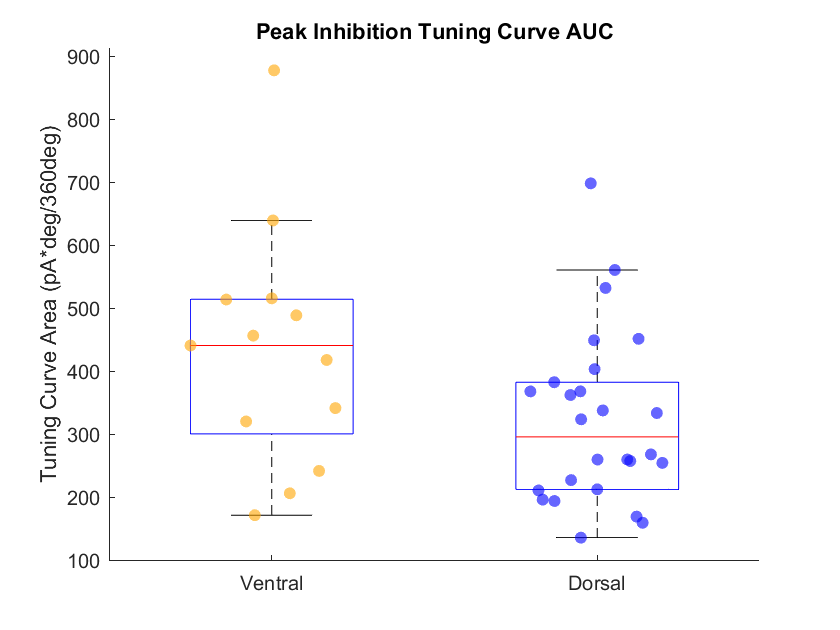

ventralTCAreas_inh = tcAreas_inh(inh_ventral_indices);
dorsalTCAreas_inh = tcAreas_inh(inh_dorsal_indices);
allPoints = [ventralTCAreas_inh'; dorsalTCAreas_inh'];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(ventralTCAreas_inh); 
groupIDs(indx1 + 1:end) = 1;

figure
title ('Peak Inhibition Tuning Curve AUC')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(ventralTCAreas_inh)), ventralTCAreas_inh,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(dorsalTCAreas_inh))+1, dorsalTCAreas_inh,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('Tuning Curve Area (pA*deg/360deg)')
box off

p = ranksum(ventralTCAreas_inh, dorsalTCAreas_inh)

p = 0.0715

## DSIs

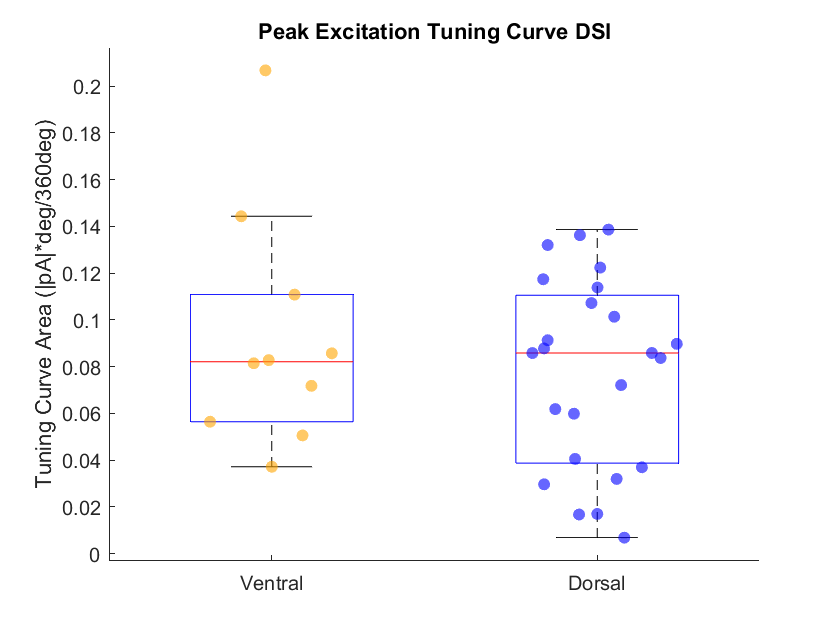

ventralDSIs_exc = DSIs_exc(exc_ventral_indices);
dorsalDSIs_exc = DSIs_exc(exc_dorsal_indices);
allPoints = [ventralDSIs_exc'; dorsalDSIs_exc'];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(ventralDSIs_exc); 
groupIDs(indx1 + 1:end) = 1;


figure
title ('Peak Excitation Tuning Curve DSI')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(ventralDSIs_exc)), ventralDSIs_exc,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(dorsalDSIs_exc))+1, dorsalDSIs_exc,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('Tuning Curve Area (|pA|*deg/360deg)')
box off

p = ranksum(ventralDSIs_exc, dorsalDSIs_exc)

p = 0.8353

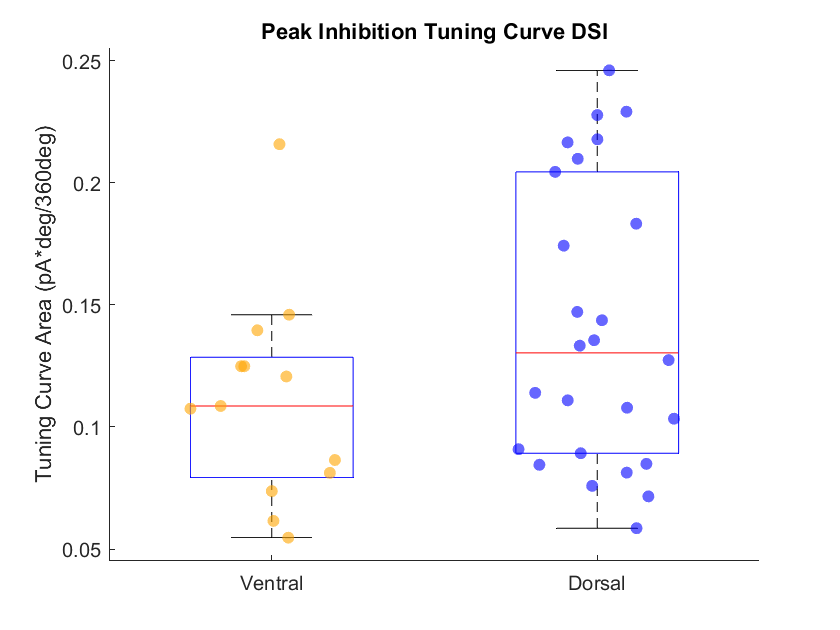

ventralDSIs_inh = DSIs_inh(inh_ventral_indices);
dorsalDSIs_inh = DSIs_inh(inh_dorsal_indices);
allPoints = [ventralDSIs_inh'; dorsalDSIs_inh'];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(ventralDSIs_inh); 
groupIDs(indx1 + 1:end) = 1;


figure
title ('Peak Inhibition Tuning Curve DSI')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(ventralDSIs_inh)), ventralDSIs_inh,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(dorsalDSIs_inh))+1, dorsalDSIs_inh,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('Tuning Curve Area (pA*deg/360deg)')
box off

p = ranksum(ventralDSIs_inh, dorsalDSIs_inh)

p = 0.1403

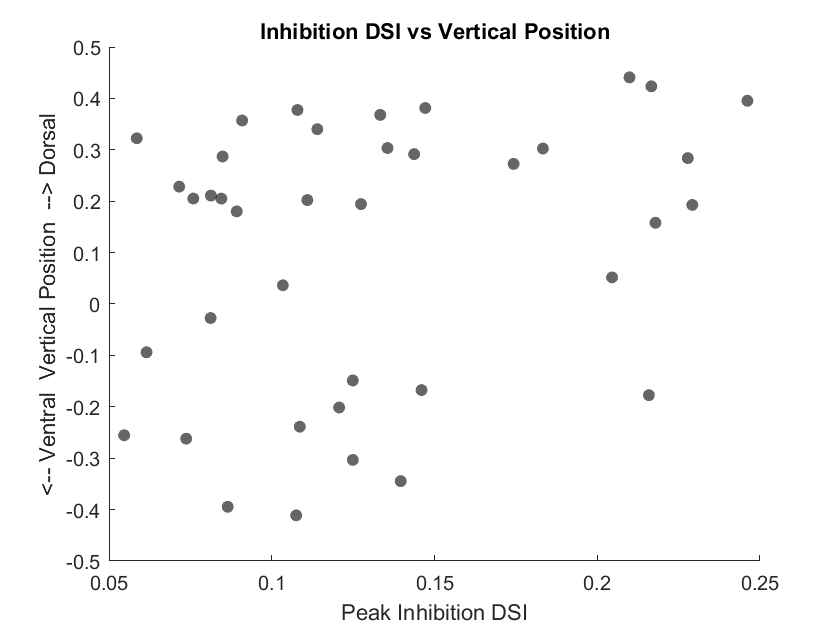

figure
title('Inhibition DSI vs Vertical Position')
hold on
scatter(DSIs_inh, coordinates(logical(inhibitionIndices), 2), 'k', 'filled', 'MarkerFaceAlpha', 0.6)
ylabel('<-- Ventral  Vertical Position  --> Dorsal')
xlabel('Peak Inhibition DSI')

[r, p] = corr(DSIs_inh', coordinates(logical(inhibitionIndices), 2), 'type','Spearman')

r = 0.2769

p = 0.0881